# Example 1: Overview of the outputs

This example presents the generation of  a turbulent wind field in a regular vertical uniform grid. The generated turbulence is assumed homogeneous and stationary. For the data used in this example, the simulation time was 10 min. Therefore, the data are directly loaded as a .mat file. To keep the size of the data small, only the first 1000 time step were saved.

## Load the data

The variables $u$, $v$ and $w$   represent the three wind velocity components. The variable  "nodes" is a structure that includes the coordinates of each nodes. The variable "t" is the time vector.

load('exampleData_V2.mat','u','v','w','nodes','t') % load the wind data

## Display the grid

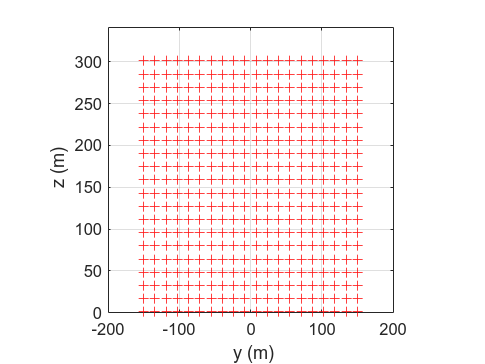


clf;close all;
figure
plot(nodes.Y(:),nodes.Z(:),'r+')
ylim([min(nodes.Y(:))-40,max(nodes.Y(:))+40])
ylim([max([0,min(nodes.Z(:))-40]),max(nodes.Z(:))+40])
grid on
xlabel(' y (m)')
ylabel(' z (m)')
pbaspect([1 1 1])

set(gcf,'color','w')


## Time series overview

The time series corresponds to the node no. 1

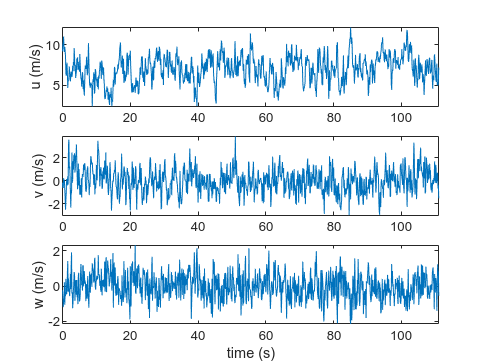

clf;close all;
figure
subplot(311)
plot(t,squeeze(u(:,1,1)))
ylabel('u (m/s)')
axis tight
subplot(312)
plot(t,squeeze(v(:,1,1)))

ylabel('v (m/s)')
axis tight
subplot(313)
plot(t,squeeze(w(:,1,1)))
xlabel('time (s)')
ylabel('w (m/s)')
axis tight

set(gcf,'color','w')


## 3D visualization of the flow


[X1,X2,X3] = meshgrid(nodes.Y(1,:)',t(:),nodes.Z(:,1)); whos X1

  Name         Size                 Bytes  Class     Attributes

  X1        1000x20x20            3200000  double              



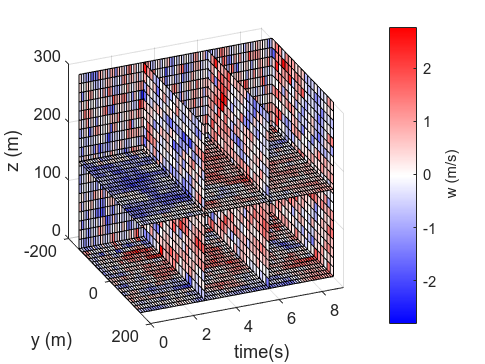


yslice = [3 6 9];
zslice = [min(nodes.Z(:,1)),mean(nodes.Z(:,1))];                               
xslice = [min(nodes.Y(:))];
clf;close all;
figure
slice(X1,X2,X3,w, xslice, yslice, zslice)    % display the slices
ylim([0 9])
view(67,28)
cb = colorbar;  
cb.Label.String = ' w (m/s)';
caxis([quantile(w(:),0.001),quantile(w(:),0.999)])
ylabel('time(s)')
xlabel('y (m)')
zlabel('z (m)')
set(gcf,'color','w')
myMap = zeros(256,3);
myMap(:,3) = [linspace(1,1,128),linspace(1,0,128)];
myMap(:,2) = [linspace(0,1,128),linspace(1,0,128)];
myMap(:,1) = [linspace(0,1,128),linspace(1,1,128)];
colormap(myMap)